# Mètode del punt fix o Mètode de la iteració simple

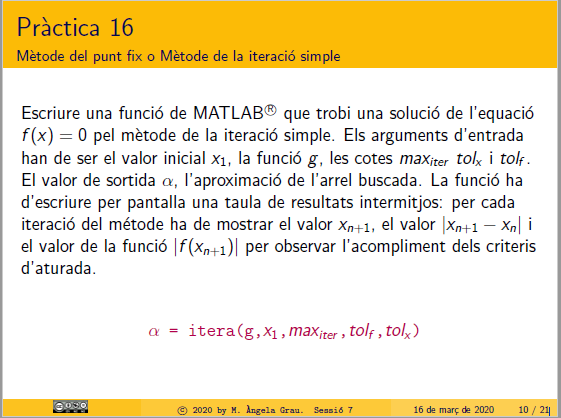  

format long E
g = @(x)cos(x); x1 = 1; maxiter = 15; tolf = 0.5*10^(-18); tolx = 0.5*10^(-18);
f = @(x)cos(x) -x;
itera(f, g, x1, maxiter, tolf, tolx)

T1 = 16×4 table
             k                      x_n                     tolf                    tolx        
    ____________________    ____________________    ____________________    ____________________

    0.00000000000000e+00    1.00000000000000e+00    1.00000000000000e+00    1.00000000000000e+00
    1.00000000000000e+00    5.40302305868140e-01    3.17250909978254e-01    4.59697694131860e-01
    2.00000000000000e+00    8.57553215846393e-01    2.03263425348614e-01    3.17250909978254e-01
    3.00000000000000e+00    6.54289790497779e-01    1.39190568244786e-01    2.03263425348614e-01
    4.00000000000000e+00    7.93480358742566e-01    9.21115851198091e-02    1.39190568244786e-01
    5.00000000000000e+00    7.01368773622757e-01    6.25909092778977e-02    9.21115851198091e-02
    6.00000000000000e+00    7.63959682900654e-01    4.18572578739465e-0

ans =      7.383692041223231e-01


# Convergència "a priori"               

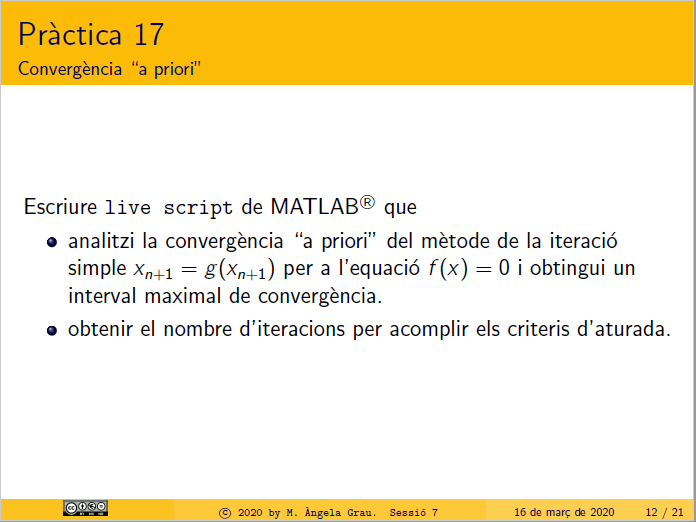

df = @(x)-cos(x)-1

df = function_handle with value:
    @(x)-cos(x)-1


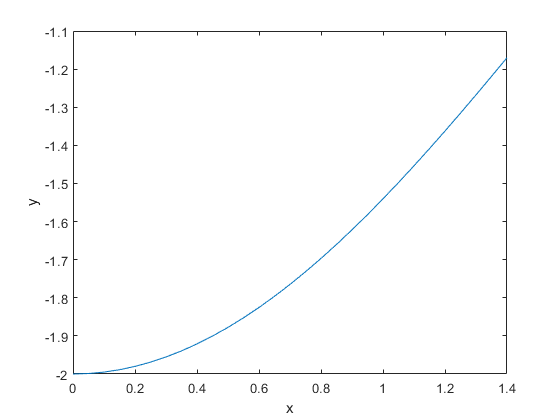

convergencia_a_priori(df)

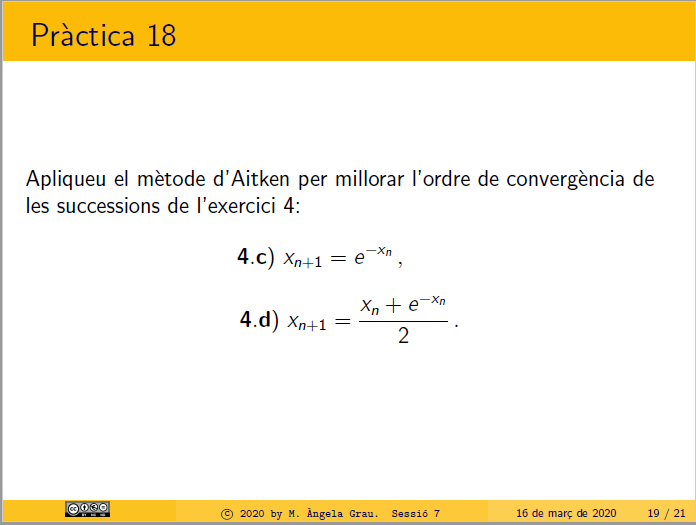

function [xnmas1] = itera(f, g, x1, maxiter, tolf, tolx)
    xnmas1 = x1;
    xn = x1;
    k = 0;
    R  = [k,x1,1,1];
    cotaf=1; 
    cotax=1;
    while(abs(cotaf) >tolx &&  abs(cotax) > tolf && k< maxiter)
        xn = xnmas1;
        xnmas1 = g(xnmas1);
        k = k+1;
        cotaf = abs(f(xnmas1));
        cotax = abs(xnmas1-xn);
        R  = [R ;k xnmas1 cotaf cotax];
    end
    T1 = array2table(R,'VariableNames',{'k','x_n','tolf','tolx'})
end
function convergencia_a_priori(df)
    t=0:0.05:1.4;
    %
    plot(t,df(t))
    xlabel('x'), ylabel('y');
    
end
